Homework #09

## 1

X=[-3.6, 1.8, -7.2, -9.6, 0.5, -0.9, -2.1, -2.8, -3.2, -2.2, 1.3, -3.6, -6.3, -0.9, -2.4, 5.2;
7.8, -7.5, -0.6, 4.5, 0.9, 0, -7, -6.8, -6.4, -9.3, -5.9, -2.5, -7.9, -6.1, 8.6, 5.4];
y=[ 1, -1, 1, 1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, 1, 1];

1a)

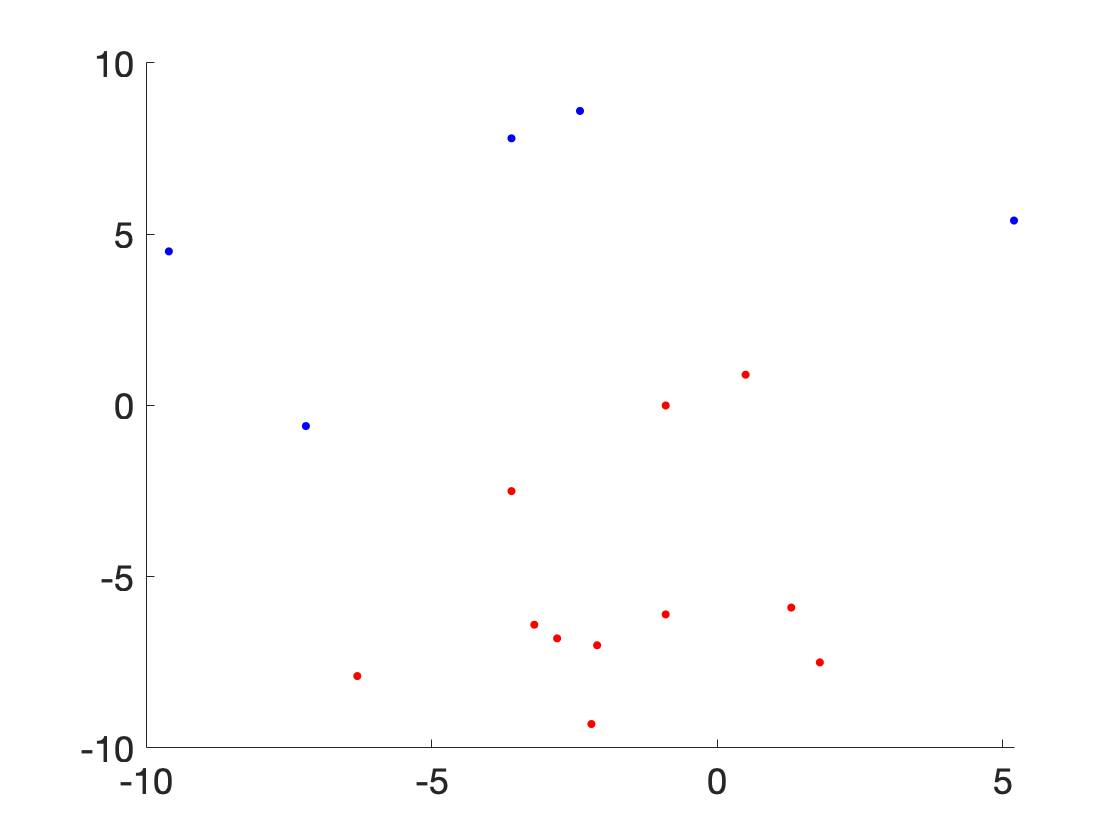

figure;hold on
color ='rgbcmyrgbcmyrgbcmyrgbcmy';
marker='......xxxxxx++++++oooooo';
for i=-1:1:1
  plot(X(1,y==i),X(2,y==i),[color(i+2) marker(i+2)],'MarkerSize',12)
end

hold off

1b)

## 2

load nonlin-percept-HW.mat
% (data, labels) X; y and initial guess for w

u=XX(1,:);v=XX(2,:);


Adapted from "perceptron_nonlinear_classification_example.m"

Parameters:

% number of data points
N=500;
% number of epochs (passes over all data points)
Nepochs=20;
% my very own fancy adjustable step:
do_adjustable_step=1;
% pause after each iteration to look carefully at what's going on:
do_pause=0;
% base rate of adjustment of perceptron coefficients:
eta0=0.01;

Initial perceptron:

w_true=[-1,-3,-1,2,3,1]';
% normalize inputs for ease of comparison to final solution:
norm1=norm([w_true]);
w_true=w_true/norm1;
fprintf(1,'true value: w_true='); disp(w_true')

true value: w_true=   -0.2000   -0.6000   -0.2000    0.4000    0.6000    0.2000




% calculate training lables based on true weights and threshold:
for i=1:N; y(i)=sign(w_true'*X(:,i));end

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.


% x,y values to use only for plotting perceptron lines, no need to change:
xx=[-1:0.02:1]; yy=[-1:0.02:1];
Nx=length(xx); Ny=length(yy);

% plot training data:
sym(1:N)='o';
sym(y<0)='x';
figure(1);clf
for i=1:N;
  plot(X(1,i),X(2,i),['b' sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(X(1,i)+0.05,X(2,i),num2str(i)); end
  hold on;
end
%xlim([-1.15 1]);ylim([-1.15 1]);
axis square

% plot initial separation line as the zero contour level:
field=calc_perceptron_contour(w,xx,yy,Nx,Ny);
[hl,hc]=contour(xx,yy,field',[0,1000],'linewidth',2,'color','k');
hold on
axis square
xlabel('X_1');
ylabel('X_2');
epoch=0;
title(sprintf('Perceptron demo: o=+1; x=-1; epoch=%d',epoch));

Training/learning loop:

for i=1:N
    % label the current data point:
  yp=w'*X(:,i);
  
  % draw currently considered data point in red, adjust previous
  % one back to blue:
  if i>1; delete(h_red_symbol); end
  h_red_symbol=plot(X(1,i),X(2,i),['r' sym(i)],'markersize',14,'linewidth',2);

  if sign(yp) ~= sign(y(i))  || sign(yp)==0
      % my addition: make the correction amplitude eta proportional to
    % how far we are from the correct answer for the current point,
    % and make the max and minimum limits go down with epoch number
    % for convergence:
    if do_adjustable_step
      if yp==0; eta=eta0/epoch; else eta=abs(yp); end
      eta=min(eta,1e-2*eta0/epoch); eta=max(eta,2*eta0/epoch);
    else
      eta=eta0;
    end
    
    % adjustment step:
    w_old=w;
    w=w+eta*y(i)*X(:,i);
    
    % normalize to order 1. is this a good idea?
    w=w/norm(w); 
    
    % plot new preceptron-derived separation line using:
    % first make older previous line blue dash: 
    %if hl_previous.MarkerSize~=0;set(hl_previous,'color','b');end
    % and make most recent previous line green dash:
    hc_previous=hc;
    set(hc_previous,'color','g','linestyle','--','linewidth',0.25);
    % then plot new line:
    field=calc_perceptron_contour(w,xx,yy,Nx,Ny);
    [hl,hc]=contour(xx,yy,field',[0,1000],'linewidth',2,'color','k');

    axis square
  end
  
title(sprintf('Perceptron demo: o=+1; x=-1; epoch=%d',epoch));
end